# Covid classification - CRNN

remove previous data

close all; clc; clear;

choose gpu

gpuSelected = "1"; % "0" | "1" | "auto"
selectGpu(gpuSelected);

gpu 1


Create audioDatastore objects of the data and split it into train, validation and test sets

datasetNames = ["voca" "coughvid" "coswara"]; % ["voca" "coughvid" "coswara"]
splitPrcnts = [0.6 0.2 0.2]; % size of train val test in [%]
shuffleDatasets = "no"; % "all" | "trainVal" | "no"
changeSubjectsOrder = "no"; % "yes" | "no"

% load data, shuffle and split to train val test
[adsTrain, adsVal, adsTest, adsSpecsTable] = ...
    loadSplitShuffleDatasets(datasetNames, splitPrcnts, shuffleDatasets, changeSubjectsOrder);
disp(adsSpecsTable);

                                         all sets           train         validation         test     
                                       _____________    _____________    ____________    _____________

    No. subjects                       "664"            "397"            "135"           "132"        
    No. Subjects (positive class)      "235 (35.4%)"    "140 (35.3%)"    "48 (35.6%)"    "47 (35.6%)" 
    No. subjects (negative class)      "429 (64.6%)"    "257 (64.7%)"    "87 (64.4%)"    "85 (64.4%)" 
    No. recordings                     "832"            "495"            "171"           "166"        
    No. recordings (positive class)    "355 (42.7%)"    "211 (42.6%)"    "73 (42.7%)"    "71 (42.8%)" 
    No. recordings (negative class)    "

choose hyper-parameters

% win & spectrogram length/overlap info
winInfo.winLen = 256;
winInfo.overlapCoeffWin = 0.75;
winInfo.overlapCoeffSpectrograms = 0.85;

% win & spectrogram normalization info
winInfo.SpectrumType = "magnitude"; % "power" "magnitude"
winInfo.WindowNormalization = false; % true false
winInfo.FilterBankNormalization = "none"; % "area" "bandwidth" "none"

% CNN
netCnnName = "vggish";
freezeLayers = "no";

% LSTM
numHiddenUnits = 512;
drop_prob = 0.3;

% training options
hyperParameters.MaxEpochs = 30;
hyperParameters.miniBatchSize = 4;
hyperParameters.InitialLearnRate = 0.00001;
hyperParameters.L2Regularization = 0.001;
hyperParameters.LearnRateSchedule = "piecewise"; % "none" "piecewise"
hyperParameters.LearnRateDropPeriod = 1; % 1 2
hyperParameters.LearnRateDropFactor = 0.99;
hyperParameters.ValidationPatience = 10; % 5 | positive integer | Inf
hyperParameters.SequencePaddingDirection = "right"; % "right" "left"
hyperParameters.SequenceLength = "longest"; % "longest" (default) | "shortest" | positive integer
hyperParameters.checkpointPath = "checkpoint"; % save net in folder after each epoch

% Streamline audio feature extraction (mel-spectrogram)

[afe, winInfo] = setAudioFeatureExtractor(winInfo);

preprocess datasets: extract auto-segmentation results from yamnet model

coughEventDetect = "yes"; % use cough event detection? "yes" | "no"
addAugment = "no";
[FeaturesTrain, trueLabelsPerAudioTrain, adsSpecsPerAudioTrain] = preprocessClassifyCrnn(adsTrain, winInfo, afe, addAugment, coughEventDetect);
addAugment = "no";
[FeaturesVal, trueLabelsPerAudioVal, adsSpecsPerAudioVal] = preprocessClassifyCrnn(adsVal, winInfo, afe, addAugment, coughEventDetect);
[FeaturesTest, trueLabelsPerAudioTest, adsSpecsPerAudioTest] = preprocessClassifyCrnn(adsTest, winInfo, afe, addAugment, coughEventDetect);

set classes and classes weights

uniqueLabels = unique(trueLabelsPerAudioVal); % ["negative" "positive"]
numClasses = 2; % No. classes
num_train_pos = sum(trueLabelsPerAudioTrain == "positive");
num_train_neg = sum(trueLabelsPerAudioTrain == "negative");
num_train = num_train_pos + num_train_neg;

% give weight to each class based on its opposite pravelance
classWeights = num_train ./ ([num_train_neg num_train_pos] * numClasses);

load relevent layers from pre-traind CNN network (yamnet/vggish)

lgraphCnn = loadCnnLgraph(netCnnName, freezeLayers);

create LSTM network

lstmLayers = [
    bilstmLayer(numHiddenUnits, 'OutputMode', 'last', 'Name', 'bilstm')
    dropoutLayer(drop_prob, 'Name', 'drop')
    fullyConnectedLayer(numClasses, 'Name', 'fc_lstm')
    softmaxLayer('Name', 'softmax')
    classificationLayer("Name", "classification", "Classes", uniqueLabels, "ClassWeights", classWeights)
    ];

assemble CNN and LSTM networks

lstm input -> folding -> CNN -> unfolding -> lstm -> classification

% create empty layer graph
lgraph = layerGraph;

% add new input layer (sequence input for lstm) and folding layer
inputSize = [96 64]; % input size needs to be the same as for CNN
layers = [
    sequenceInputLayer([inputSize 1], 'Name', 'input') % sequence input for lstm
    sequenceFoldingLayer('Name', 'fold') % change structure for CNN
    ];

% connect new input layers to input of CNN
lgraph = addLayers(lgraph, layers);
lgraph = addLayers(lgraph, lgraphCnn.Layers);
lgraph = connectLayers(lgraph, "fold/out", string(lgraphCnn.Layers(1, 1).Name));

% add unfolding and lstm layers
layers = [
    sequenceUnfoldingLayer('Name', 'unfold') % change structure back for lstm
    flattenLayer('Name', 'flatten') % change dim from [1, 1, No. output features] to [No. output features, 1]
    lstmLayers
    ];

% connect unfolding and lstm layers to output of CNN
lgraph = addLayers(lgraph, layers);
lgraph = connectLayers(lgraph, string(lgraphCnn.Layers(end, 1).Name), "unfold/in");

% add parallel connection between folding & unfolding layers (needed to restore the sequence structure)
lgraph = connectLayers(lgraph, "fold/miniBatchSize", "unfold/miniBatchSize");

% % analyze network
% figure;
% plot(lgraph);
% analyzeNetwork(lgraph);

specify training options

numObservations = numel(FeaturesTrain);
validationFrequency = floor(numObservations / hyperParameters.miniBatchSize);

options = trainingOptions( ...
    'adam', ...
    'Plots', 'training-progress', ... % 'none' (default) | 'training-progress'
    'Verbose', true, ... % 1 (true) (default) | 0 (false)
    'MaxEpochs', hyperParameters.MaxEpochs, ...
    'MiniBatchSize', hyperParameters.miniBatchSize, ...
    'Shuffle', 'every-epoch', ... % 'once' (default) | 'never' | 'every-epoch'
    'ExecutionEnvironment', 'auto', ... % 'auto' (default) | 'cpu' | 'gpu' | 'multi-gpu' | 'parallel'
    ...
    'ValidationData', {FeaturesVal, trueLabelsPerAudioVal}, ...
    'ValidationFrequency', validationFrequency, ...
    'InitialLearnRate', hyperParameters.InitialLearnRate, ...
    'LearnRateSchedule', 'piecewise', ... % piecewise, none
    'LearnRateDropPeriod', 1, ...
    'LearnRateDropFactor', hyperParameters.LearnRateDropFactor, ...
    'L2Regularization', hyperParameters.L2Regularization, ...
    'ValidationPatience', hyperParameters.ValidationPatience, ...
    ...
    'SequencePaddingDirection', hyperParameters.SequencePaddingDirection, ...
    'SequenceLength', hyperParameters.SequenceLength, ...% "longest" (default) | "shortest" | positive integer
    ...
    'CheckpointPath', hyperParameters.checkpointPath, ...
    'BatchNormalizationStatistics', 'moving' ... % 'population' (default) | 'moving'
    );

Train the LSTM network with the specified training options.

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |       25.00% |       61.54% |       0.6148 |       0.6879 |      1.0000e-05 |
|       1 |          50 |       00:00:30 |       50.00% |              |       0.7237 |              |      1.0000e-05 |
|       1 |         100 |       00:00:48 |      100.00% |              |       0.6121 |              |      1.0000e-05 |
|       1 |         121 |       00:01:02 |       50.00% |       64.50% |       0.6059 |       0.6763 |      1.0000e-05 |
|       

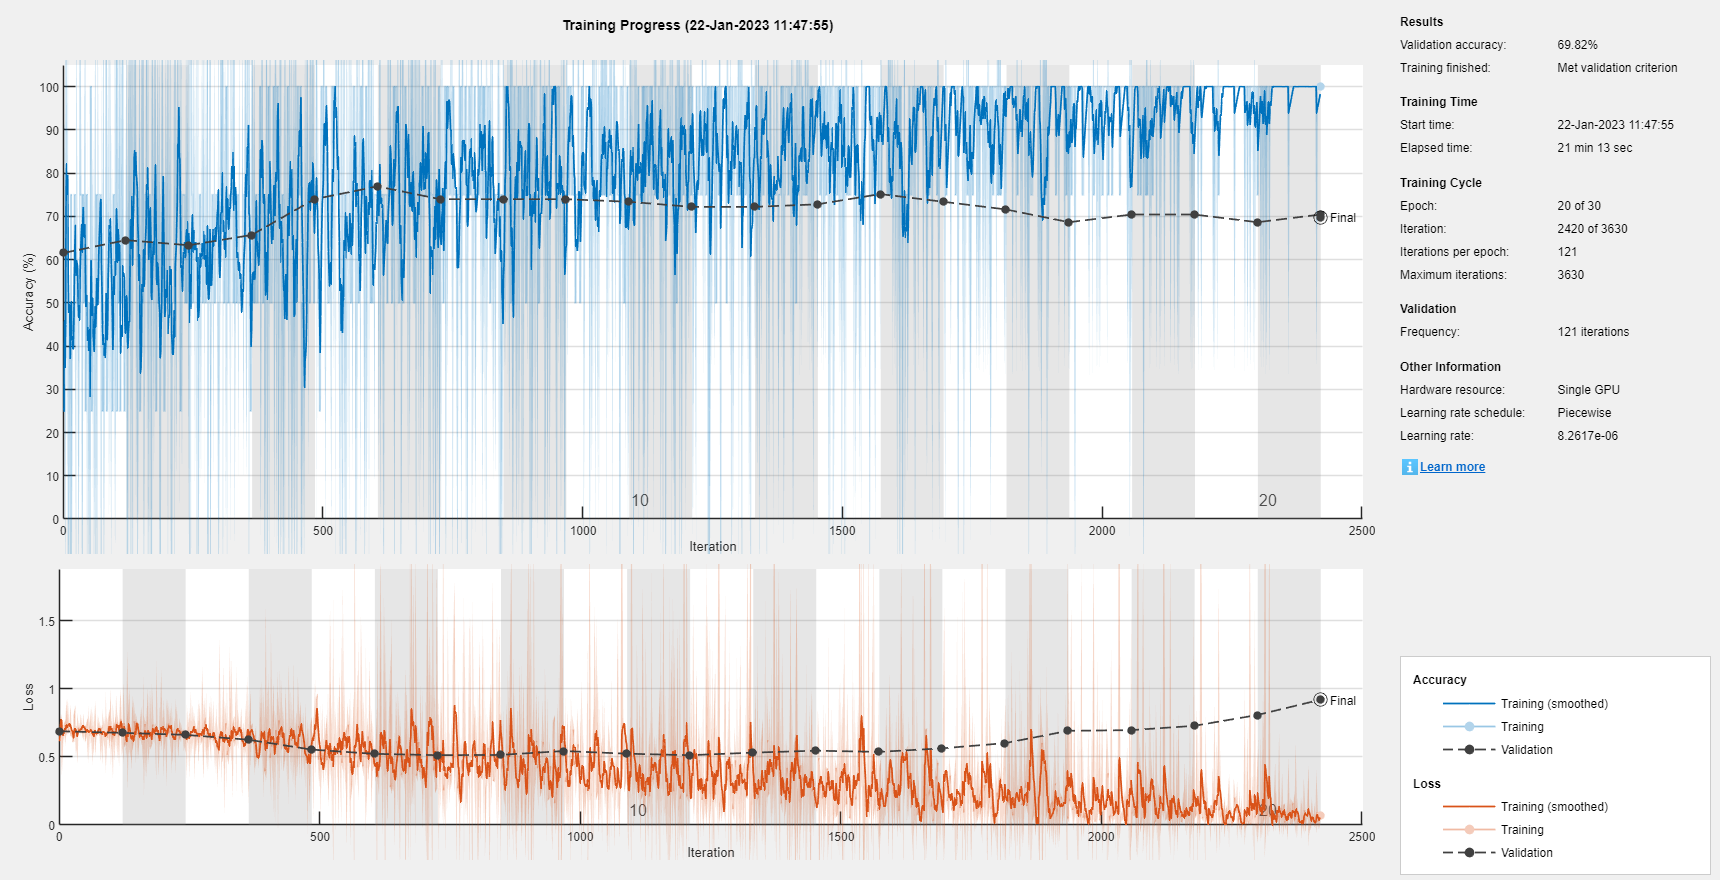

% remove saved nets from previous training
delete(hyperParameters.checkpointPath + "/*");

% train network
[~, net_info] = trainNetwork(FeaturesTrain, trueLabelsPerAudioTrain, lgraph, options);

load net (out of all nets yelded from current training) from epoch with best result (lowest validation error)

net_classification_CRNN = extractNetFromCheckpoint(net_info, hyperParameters.checkpointPath);

best epoch:
10


remove saved nets after training

delete(hyperParameters.checkpointPath + "/*");

predict on train, val and test sets (probability [0,1]).

miniBatchSize_predict = 1;
positive_indx = find(string(uniqueLabels) == "positive");
predLabelsPerAudioTrain = predict(net_classification_CRNN, FeaturesTrain, 'MiniBatchSize', miniBatchSize_predict);
predLabelsPerAudioTrain = predLabelsPerAudioTrain(:, positive_indx);
predLabelsPerAudioVal   = predict(net_classification_CRNN, FeaturesVal, 'MiniBatchSize', miniBatchSize_predict);
predLabelsPerAudioVal   = predLabelsPerAudioVal(:, positive_indx);
predLabelsPerAudioTest  = predict(net_classification_CRNN, FeaturesTest, 'MiniBatchSize', miniBatchSize_predict);
predLabelsPerAudioTest  = predLabelsPerAudioTest(:, positive_indx);

change predictions and true labels from per audio signal to per subject

[predLabelsPerSubjTrain, trueLabelsPerSubjTrain, adsSpecsPerSubjTrain] = ...
    perAudio2perSubject(predLabelsPerAudioTrain, trueLabelsPerAudioTrain, adsSpecsPerAudioTrain);
[predLabelsPerSubjVal, trueLabelsPerSubjVal, adsSpecsPerSubjVal] = ...
    perAudio2perSubject(predLabelsPerAudioVal, trueLabelsPerAudioVal, adsSpecsPerAudioVal);
[predLabelsPerSubjTest, trueLabelsPerSubjTest, adsSpecsPerSubjTest] = ...
    perAudio2perSubject(predLabelsPerAudioTest, trueLabelsPerAudioTest, adsSpecsPerAudioTest);

find best ROC thrshold on val set, and plot ROC curve

plot ROC curve and confusion matrix on test set.

display for train, val and test sets:

- ROC & AUC

- confusion matrix

- accuracy, UAR (unweighted average recall), F1 score, sensetivity, PPV, specificity

accuracy = (TP + TN) / (TP + TN + FP + FN)

UAR = (sensetivity + specificity) / 2

F1-score = 2 * (PPV * sensitivity) / (PPV + sensitivity)

sensitivity = TP / (TP + FN)

PPV = TP / (TP + FP)

specificity = TN / (TN + FP)

ROC for VAL set:


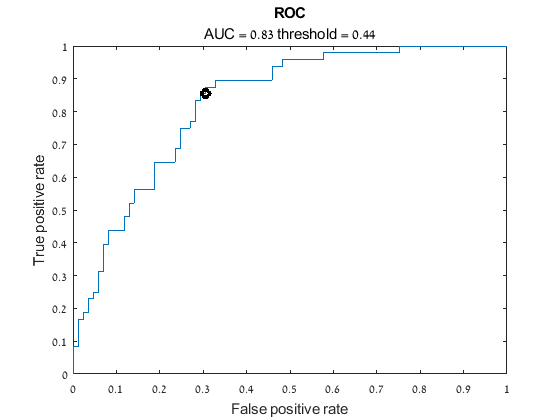

ROC for TEST set:


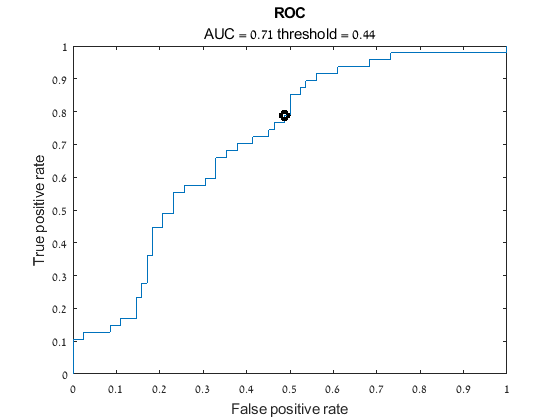

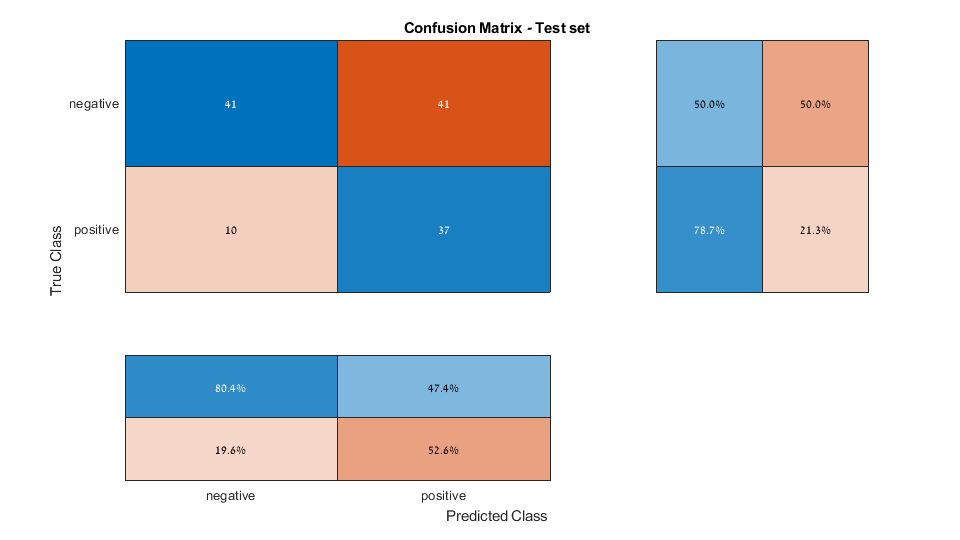

scores:
                       accuracy [%]    UAR [%]    F1 [%]    sensitivity [%]    PPV [%]    specificity [%]    AUC [%]
                       ____________    _______    ______    _______________    _______    _______________    _______

    train                 80.412         83.9     78.035        96.429         65.534         71.371         92.849 
    val                    75.94       78.456     72.414          87.5         61.765         69.412         82.647 
    test                  60.465       64.362       59.2        78.723         47.436             50         70.758 
    testAgeLow            56.452       58.943     50.909        66.667         41.176          51.22

specificityThershold = 0; % choose threshold for minimum specificity score
rocThreshold = 0; % choose threshold for ROC curve
setRocThreshold = "auto"; % define if to use manual threshold or auto decision

lblsPredCell        = {predLabelsPerSubjTrain predLabelsPerSubjVal predLabelsPerSubjTest};
lblsTrueCell        = {trueLabelsPerSubjTrain trueLabelsPerSubjVal trueLabelsPerSubjTest};
adsSpecsPerSubjCell = {adsSpecsPerSubjTrain adsSpecsPerSubjVal adsSpecsPerSubjTest};

extractClassifyScoresCrnn( ...
    lblsPredCell, lblsTrueCell, adsSpecsPerSubjCell, ...
    specificityThershold, setRocThreshold, rocThreshold ...
    );